## Plotting maxTreeDepth_Time

dic=readtable('treeDepth_time_nmec.txt')

dic = 40000×3 table
       Var1          Var2          Var3   
    __________    __________    __________

    0.0000e+00    3.9000e+01    6.5650e-03
    1.0000e+00    4.3000e+01    6.9780e-03
    2.0000e+00    4.1000e+01    7.4170e-03
    3.0000e+00    3.8000e+01    7.9940e-03
    0.0000e+00    3.9000e+01    9.8190e-03
    1.0000e+00    4.3000e+01    7.2210e-03
    2.0000e+00    4.1000e+01    1.2190e-02
    3.0000e+00    3.8000e+01    8.1930e-03
    0.0000e+00    3.9000e+01    1.0100e-02
    1.0000e+00    4.3000e+01    9.8880e-03
    2.0000e+00    4.1000e+01    9.6010e-03
    3.0000e+00    3.8000e+01    1.0040e-02
    0.0000e+00    3.9000e+01    8.2310e-03
    1.0000e+00    4.3000e+01    1.0650e-02
    2.0000e+00    4.1000e+01    9.8580e-03
    3.0000e+00    3.8000e+01    8.2390e-03


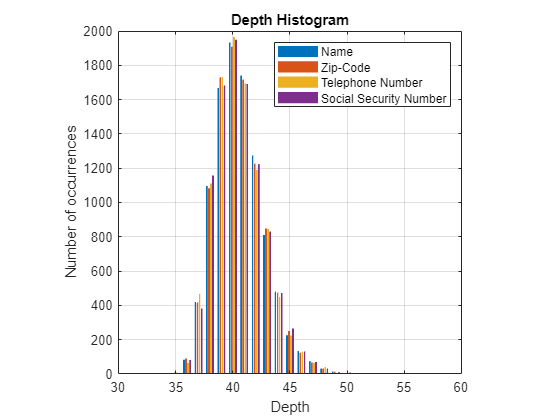

% nMec = [990000 : 1 : 999999];
depths = table2array(dic(:,2));
index = 1;
for i=1:4:40000
    depth1(index) = depths(i,1);
    depth2(index) = depths(i+1,1);
    depth3(index) = depths(i+2,1);
    depth4(index) = depths(i+3,1);
    index=index+1;
end
binspan=(34:56);
A1 = hist(depth1,binspan);
B1 = hist(depth2,binspan);
C1 = hist(depth3,binspan);
D1 = hist(depth4,binspan);
figure(1);
x = 34:1:56;
y = [A1;B1;C1;D1];
bar(x,y,EdgeColor="none");
axis square;
grid on;
xlabel("Depth");
ylabel("Number of occurrences");
title('Depth Histogram');
legend("Name","Zip-Code","Telephone Number", "Social Security Number");

## Plotting search_time histogram

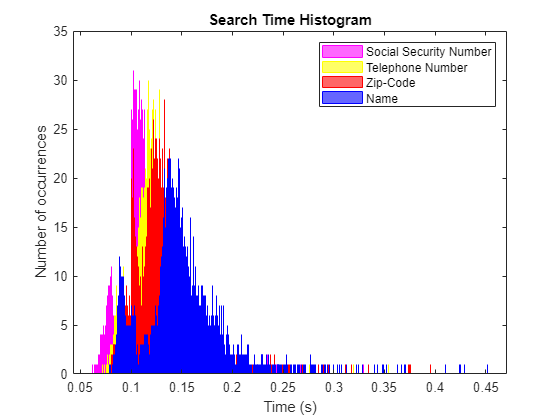

% search=readtable('search_Time_nmec.txt')
% passando a table para .txt para input facilitado
% writetable((search(:,3)), 'searchTimeHistogram.txt')
stimes = dlmread('searchTimeHistogram.txt');
index = 1;
for i=1:4:40000
    search1(index) = stimes(i,1);
    search2(index) = stimes(i+1,1);
    search3(index) = stimes(i+2,1);
    search4(index) = stimes(i+3,1);
    index=index+1;
end
figure(2);
histogram(search4,"BinWidth",0.000001,FaceColor="magenta",EdgeColor="magenta");
hold on
histogram(search3,"BinWidth",0.000001,FaceColor="yellow",EdgeColor="yellow");
hold on
histogram(search2,"BinWidth",0.000001,FaceColor="red",EdgeColor="red");
hold on
histogram(search1,"BinWidth",0.000001,FaceColor="blue",EdgeColor="blue");
title('Search Time Histogram');
xlabel("Time (s)");
ylabel("Number of occurrences");
legend("Social Security Number", "Telephone Number", "Zip-Code", "Name");
hold off

## Plotting Tree_Creation_Time Histogram

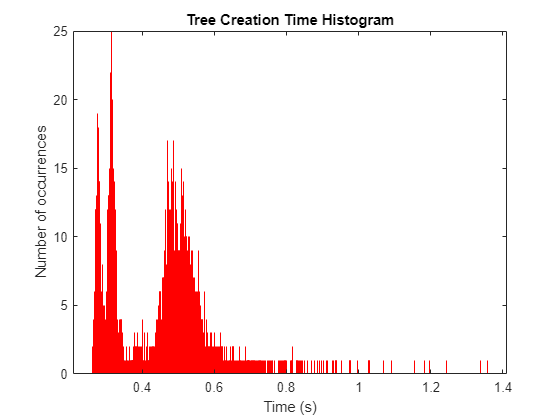

% creation=readtable('creation_time_nmec.txt')
% % passando a table para .txt para input facilitado
% writetable((creation(:,2)), 'creationTimeHistogram.txt')
a = dlmread('creationTimeHistogram.txt');
for i=1:10000
    c1(i) = a(i,1);
end
histogram(c1,"BinWidth",0.0001,EdgeColor="red");
xlabel("Time (s)");
ylabel("Number of occurrences");
title('Tree Creation Time Histogram');